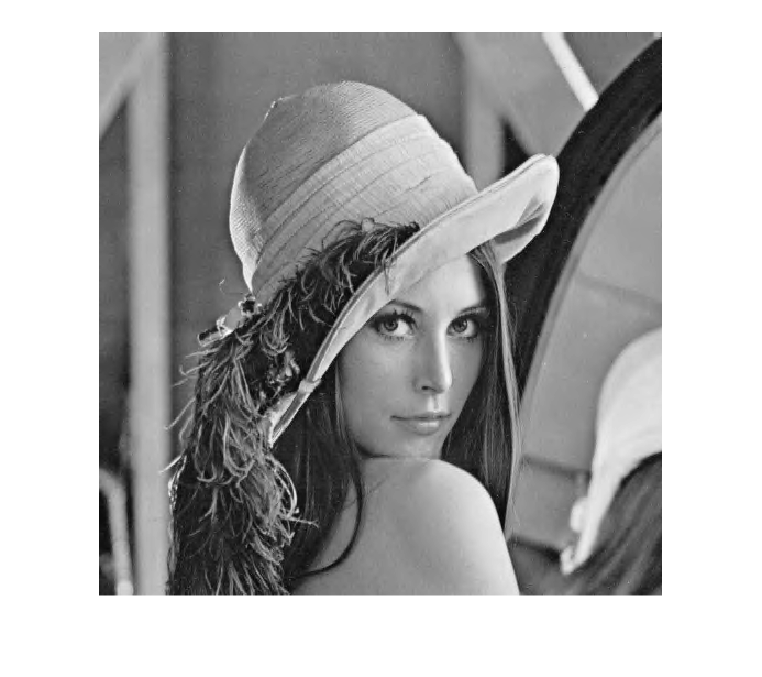

img = im2double(im2gray(imread("lenna.tif")));
imshow(img,[]);

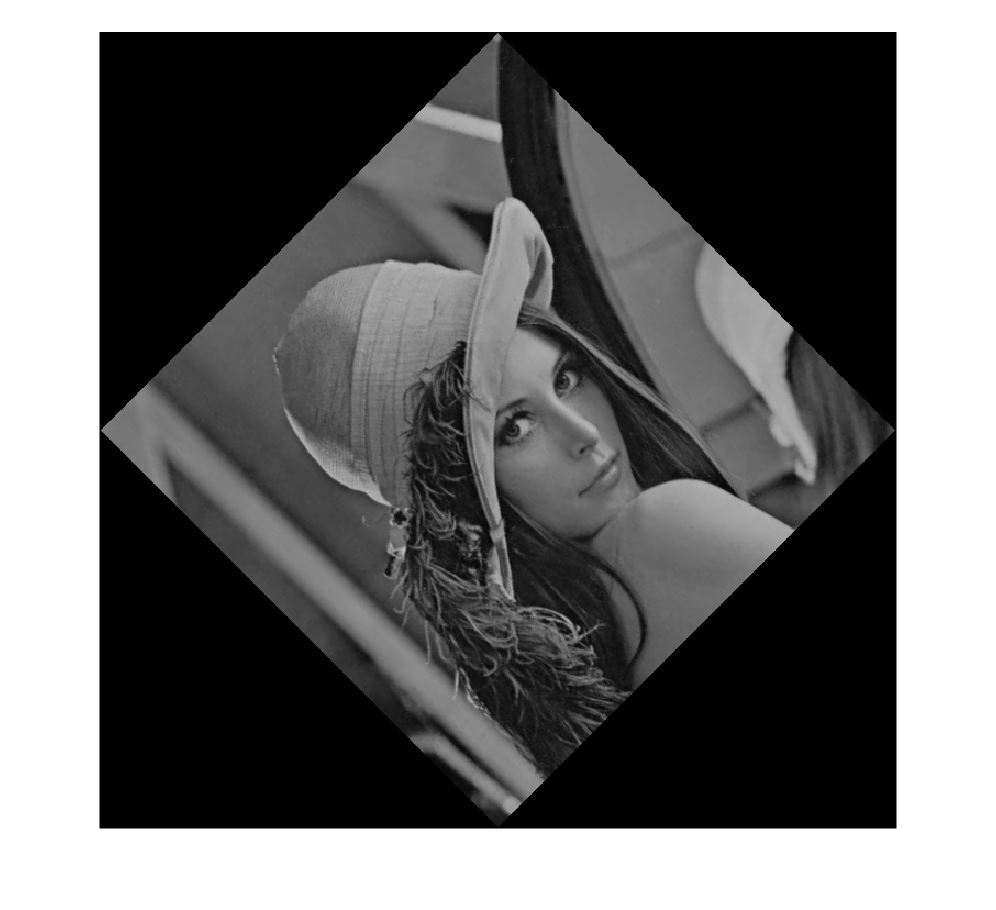

theta = pi/4;
T = [cos(theta) sin(theta) 0;
      -sin(theta) cos(theta) 0;
      0           0           1];
tform = affinetform2d(T);
imgTform = imwarp(img, tform);
imshow(imgTform)

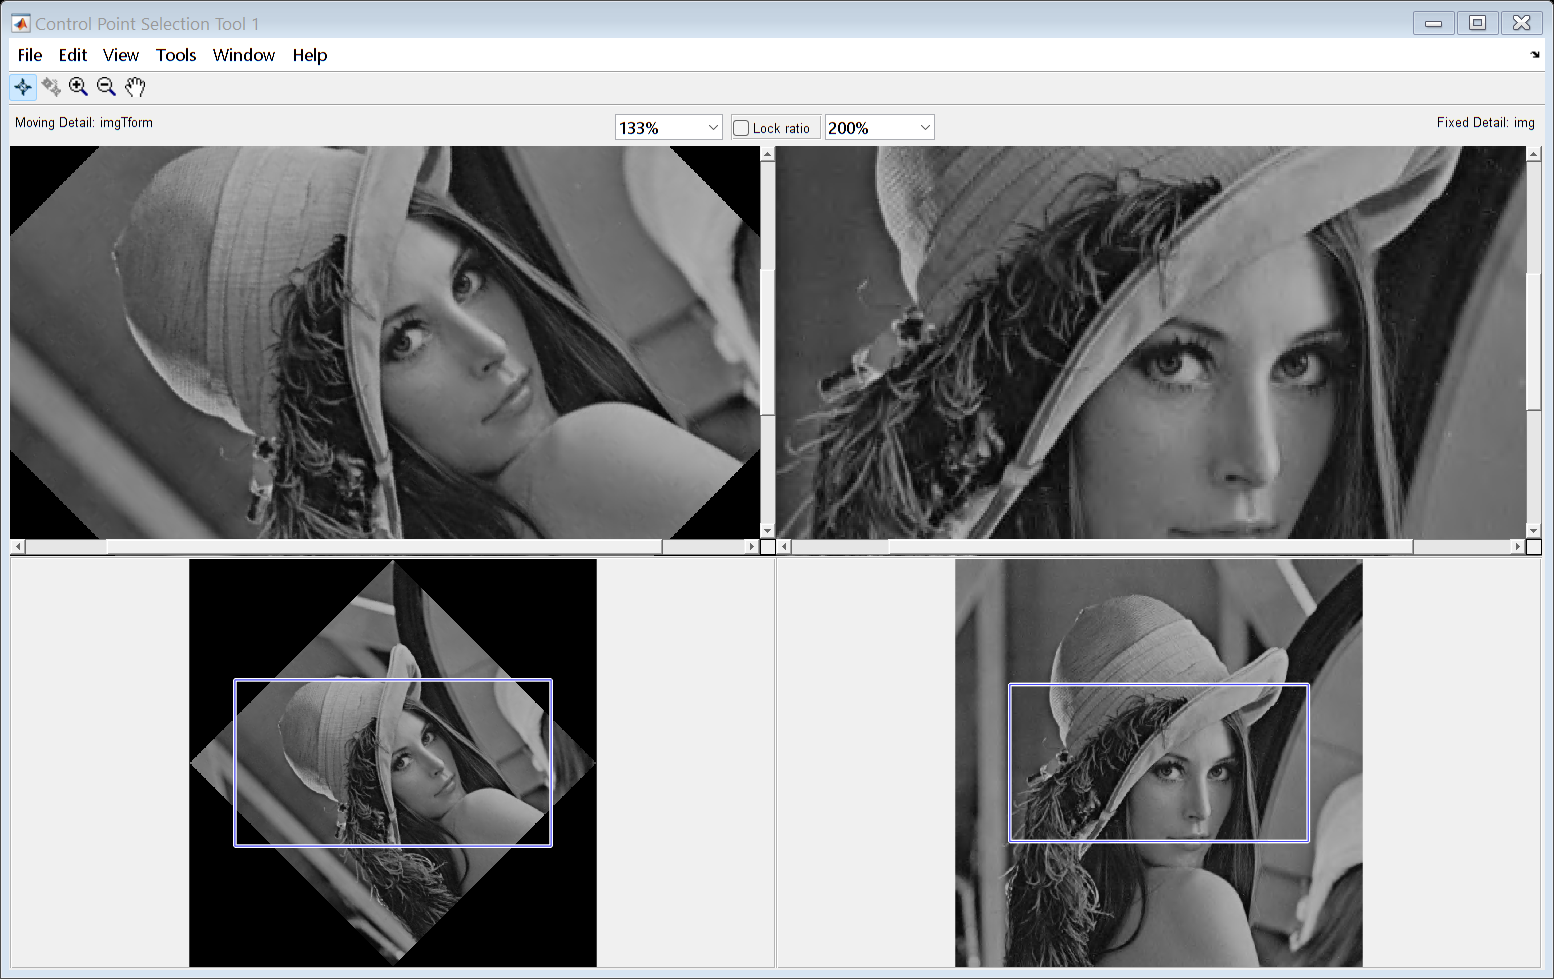

cpselect(imgTform, img);

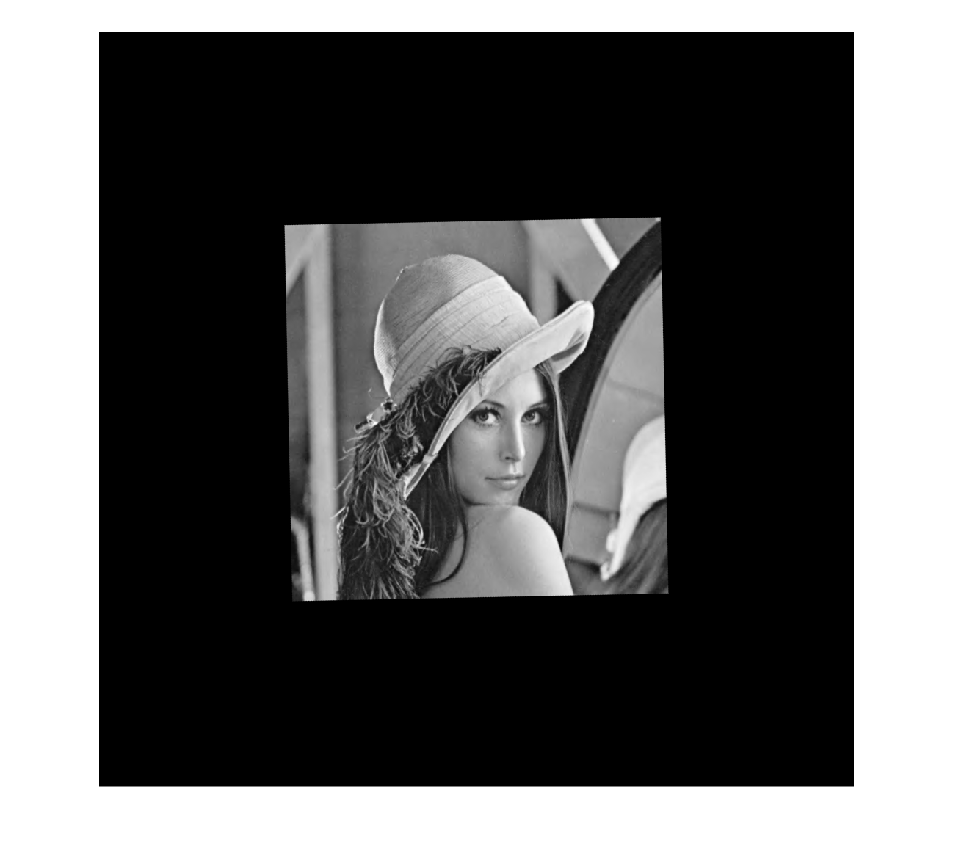

movingPointsAdjusted = cpcorr(movingPoints, fixedPoints, img, imgTform);
cptform = fitgeotform2d(movingPointsAdjusted,fixedPoints,"similarity");
restoredImg = imwarp(imgTform,cptform);
imshow(restoredImg,[])